% light compensation

img = imread('../TNM034/Facial-recognition/facedetection/grayworld.png')

img = 592×477×3 uint8 array
img(:,:,1) =

   180   181   181   180   179   180   180   179   179   181   182   180   179   180   181   180   175   177   180   179   180   182   181   185   184   183   181   181   178   174   178   182   186   183   183   185   188   198   203   208   209   210   207   205   204   200   194   187   189   186   189   190   191   183   191   170   153   179   189   185   174   154   171   172   185   168   141   151   162   183   188   184   184   181   188   189   164   173   188   184   186   189   186   186   195   199   197   191   184   181   179   185   181   185   180   177   179   184   177   179   190   189   189   187   189   182   179   180   182   179   185   189   184   187   183   184   185   189   185   187   188   187   187   187   188   189   189   190   187   187   187   187   187   187   187   187   185   188   189   189   191   190   185   187   187   188   187   187   186   185   185   184   189   187   184   189   189   187   192   1

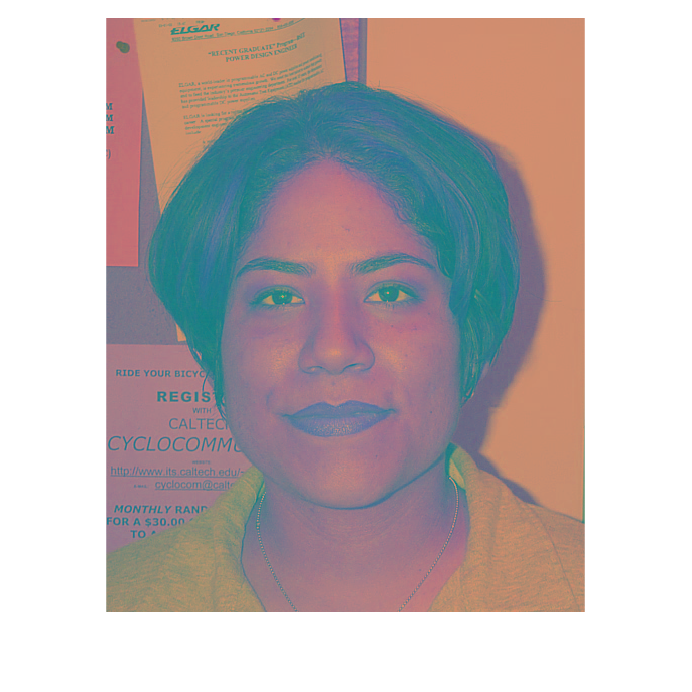



% binary image 
bin_img = zeros(size(img,1),size(img,2));

% YCbCr
YCbCr_img = rgb2ycbcr(img);
%C1 = double(YCbCr_img);
imshow(YCbCr_img)

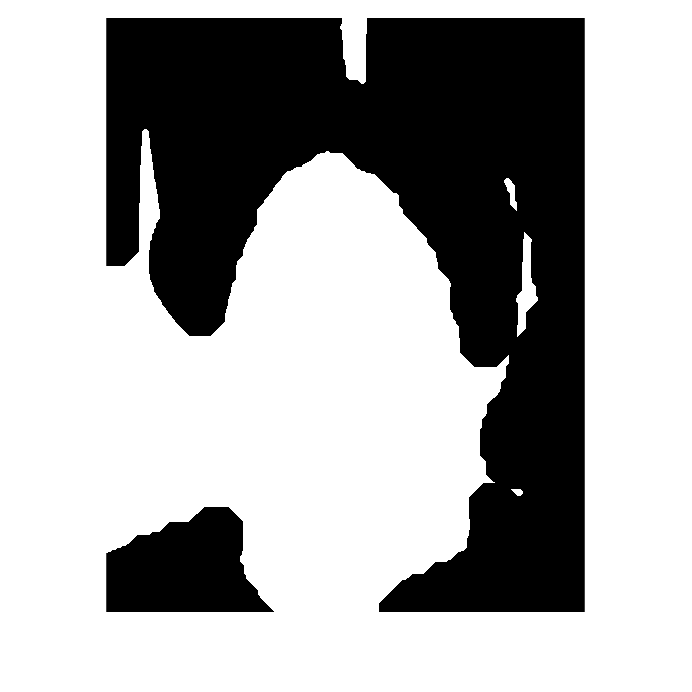


y=YCbCr_img(:,:,1);
cb=YCbCr_img(:,:,2);
cr=YCbCr_img(:,:,3);

% Threshold
[row,col] = find(cb >= 65 & cb <= 200 & cr >= 131 & cr <= 155 & y >= 80);

% Change skin color

for k = 1:size(row)
    bin_img(row(k),col(k)) = 1;
end

% Morphology
%kernel = strel('disk',20);
%bin_img = imclose(bin_img,kernel);
SE = strel('disk',4);
bin_img = imopen(bin_img, SE);
SE1 = strel('disk',25);
bin_img = imclose(bin_img, SE1);

bin_img = imfill(bin_img, 'holes');
target = 256:-4:4;
bin_img = histeq(bin_img,target);
bin_img = imbinarize(bin_img,0.9);

binary_img = bwareafilt(bin_img,1);
imshow(bin_img)